% Header

# Control System Oscillation 

A control system is designed to respond to an instantaneous change in signal level, like a switch turning on. If the control system is underdamped, the response will produce an oscillation, modeled as:

### 
$$s\left(t\right)=A\left\lbrack 1-e^{-\textrm{bt}} \;\cos \left(2\pi \;f_d \;t-\phi \;\right)\right\rbrack$$


where $A$ is the signal level in volts [V] when the switch is turned on, $b$ is the damping factor [$s^{-1}$], $f{\;}_d$ is the oscillation frequency [Hz], and $\phi \;$the intial phase of the oscillation in radians.

Create a proper plot of the underdamped system response, s, (i.e., 'System Response (s) [V]') as a function of time for two different damping functions, $b_1$ and $b_2$. 

**Additional requirements: **

- Do not use loops of any kind.

- Suppress all non-graphical output.

- Example legend entry: $b_1 =5s^{-1}$

- Damping factor 1 line style: solid blue line.

- Damping factor 2 line style: dashed red line.

- Graph title: **Control System Oscillation: username**

% Housekeeping
clc;clear;close all

 
% Input variables
A    = 5;   % signal level [volts]
b1   = 5;   % damping factor 1 [per second]
b2   = 12;  % damping factor 1 [per second]
f_D  = 2.5; % oscillation frequency [Hz]
phi  = 0;   % initial phase [radians]
tmax = 3;   % maximum time to use in graph [seconds]

% Make graph
figure()
t=0:.001:tmax

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


s_t_1=A*(1-exp(-b1.*t).*cos(2*pi*f_D*t-phi))

s_t_1 =          0    0.0256    0.0522    0.0799    0.1087    0.1385    0.1693    0.2011    0.2339    0.2677    0.3024    0.3380    0.3746    0.4120    0.4503    0.4895    0.5294    0.5702    0.6118    0.6541    0.6972    0.7411    0.7856    0.8309    0.8768    0.9234    0.9706    1.0185    1.0669    1.1159    1.1655    1.2156    1.2663    1.3175    1.3691    1.4212    1.4738    1.5268    1.5802    1.6340    1.6882    1.7427    1.7976    1.8528    1.9082    1.9640    2.0201    2.0763    2.1329    2.1896


s_t_2=A*(1-exp(-b2.*t).*cos(2*pi*f_D*t-phi))

s_t_2 =          0    0.0603    0.1210    0.1822    0.2437    0.3057    0.3680    0.4306    0.4935    0.5566    0.6200    0.6835    0.7472    0.8111    0.8750    0.9390    1.0031    1.0672    1.1313    1.1953    1.2594    1.3233    1.3871    1.4509    1.5144    1.5779    1.6411    1.7041    1.7669    1.8295    1.8918    1.9539    2.0156    2.0770    2.1381    2.1989    2.2593    2.3193    2.3789    2.4382    2.4970    2.5554    2.6133    2.6708    2.7278    2.7844    2.8404    2.8960    2.9511    3.0056


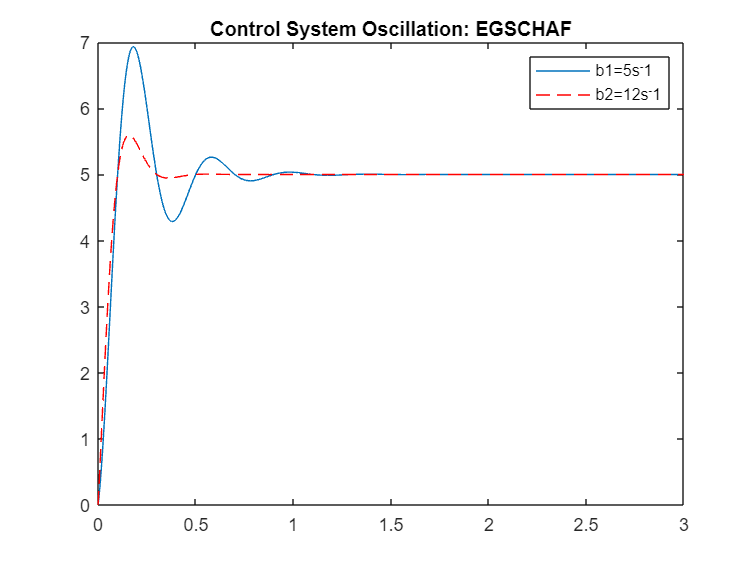

plot(t,s_t_1);hold on
plot(t,s_t_2,'LineStyle','--','Color','r')
legend(sprintf('b1=%0.0fs^-1',b1),sprintf('b2=%0.0fs^-1',b2))
title('Control System Oscillation: EGSCHAF')

% Housekeeping
clc;clear;close all

 
% Input variables
A    = 5;   % signal level [volts]
b1   = 5;   % damping factor 1 [per second]
b2   = 12;  % damping factor 1 [per second]
f_D  = 2.5; % oscillation frequency [Hz]
phi  = 0;   % initial phase [radians]
tmax = 3;   % maximum time to use in graph [seconds]
Mar=[b1,b2]

Mar =      5    12


% Make graph
figure('Color','g')
t=0:.0001:tmax

t =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


lin={'-','--'}

lin = 1×2 cell array
    {'-'}    {'--'}


col={'b','r'}

col = 1×2 cell array
    {'b'}    {'r'}


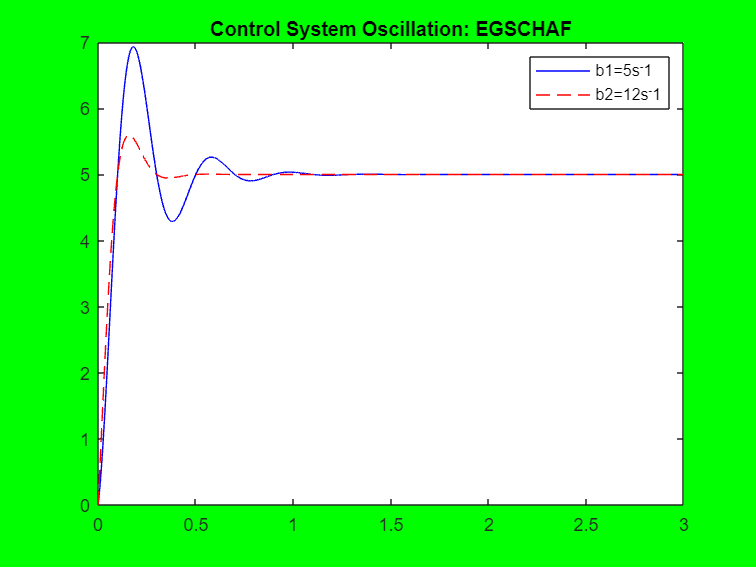

for p=1:2
    plot(t,A*(1-exp(-Mar(p).*t).*cos(2*pi*f_D*t-phi)),'LineStyle',lin{p},'color',col{p})
    hold on
end
legend(sprintf('b1=%0.0fs^-1',b1),sprintf('b2=%0.0fs^-1',b2))
title('Control System Oscillation: EGSCHAF')